% Test med databas

dataBase = cell(51, 1);

for i = 1:51
    dataBase{i} = imread(['Database_logos/' int2str(i) '.jpg']);
end

save dataBase dataBase

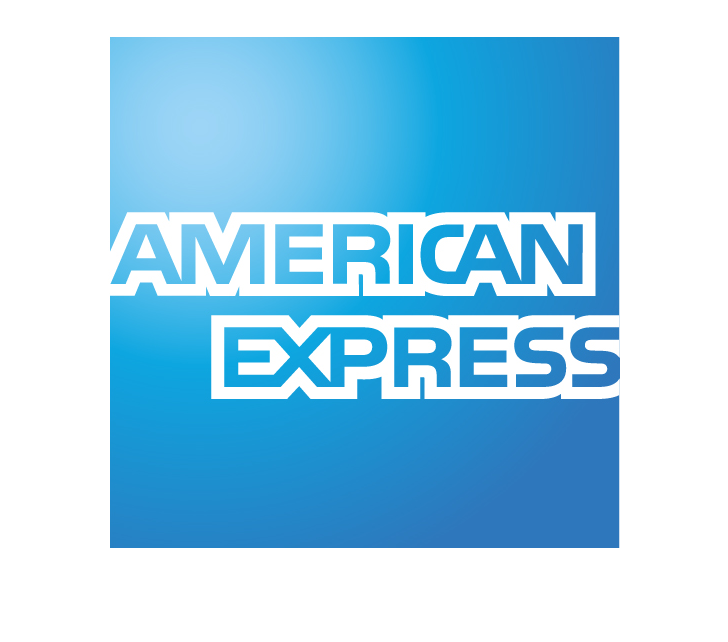

load dataBase

% imshow(dataBase{1})


colorBase = cell(51, 1);

for i = 1:51
    currentImage = dataBase{i};
    
    if size(currentImage, 3) == 1
        currentImage = cat(3, currentImage, currentImage, currentImage);
    end
    
    R = currentImage(:, :, 1);
    G = currentImage(:, :, 2);
    B = currentImage(:, :, 3);
    
    colorBase{i} = struct('Red', R, 'Green', G, 'Blue', B);
end

save colorBase colorBase

load colorBase

firstImageStruct = colorBase{1};

sumRed = sum(sum(firstImageStruct.Red))

sumRed = 23084578

sumGreen = sum(sum(firstImageStruct.Green))

sumGreen = 45979737

sumBlue = sum(sum(firstImageStruct.Blue))

sumBlue = 58347887


test = cat(3, redChannel,greenChannel,blueChannel);

imshow(test);